%11 decay rate of compound

t = 0.0:0.25:2.5;
mlist = zeros(1,11);
for i = 1:length(t)
   m = 0.3 + quad('-0.69*exp(-2.3*t)', 0.0, t(i));
   mlist(i) = m;  % or in a single line without m
end
[t' mlist']

ans =          0    0.3000
    0.2500    0.1688
    0.5000    0.0950
    0.7500    0.0535
    1.0000    0.0301
    1.2500    0.0169
    1.5000    0.0095
    1.7500    0.0054
    2.0000    0.0030
    2.2500    0.0017


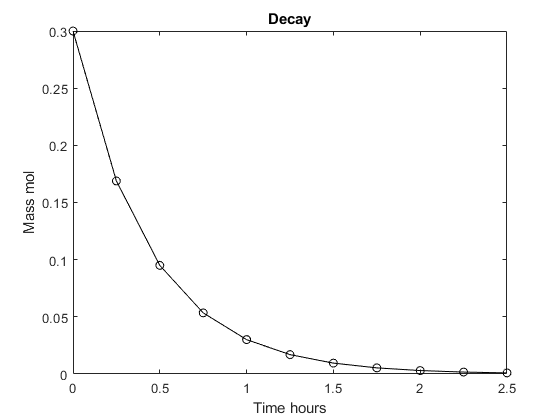

plot(t,mlist, '-ok');
xlabel('Time hours'), ylabel('Mass mol');
title('Decay');